# Eigenwerte als Nullstellen des charakteristischen Polynoms

Wir betrachten die  $n \times n$ Diagonalmatrix $A={\rm diag}(3.1,3,3 \ldots,3) $, mit Eigenwerten 3.1 und 3 ($(n-1)$-fach).

Der Wert für $n$ wird gewählt:

fprintf('\nDimension der Matrix: \n');


Dimension der Matrix: 


n=6

n = 6

Das charakteristische Polynom von $A$ wird bestimmt und (ggf. komplexe) Annäherungen der Nullstellen dieses Polynoms werden mit der MATLAB-Routine `roots` bestimmt.

Das charakterische Polynom hat in der monomialen Darstellung die Form

$
\sum_{k=0}^n \alpha_k \lambda^k,~ \text{mit} ~ \alpha_0  =3.1 \cdot3^{n-1}, ~\alpha_n=(-1)^n, ~~ \alpha_k  =(-1)^k 3^{n-1-k} \left(3.1 \pmatrix{n-1 \cr k} + 3\pmatrix{n-1 \cr k-1} \right), ~k=1,\ldots,n-1$.

Für die Routine `roots` wird als Eingabe der Koeffizientvektor $c_k:=\alpha_{n+1-k}$, $k=1,\ldots,n+1$, benötigt, also in umgekehrter Reihenfolge (siehe "`help roots`" in Matlab).

Der Fehler in der Annäherung des größten Eigenwertes $\lambda_1=3.1$ wird berechnet. Die exakten Eigenwerte und die berechneten Annäherungen (Nullstellen des charakteristischen Polynoms) werden geplottet. 

# Aktivität:

Variieren Sie die Dimension $n$, z.B., $n \in \{3,6,9,12,15\}$ und betrachten Sie die Genauigkeiten der Eigenwertapproximationen. 

Es stellt sich heraus, dass diese Methode bereits für moderate $n$ Werte *nicht stabil *ist.

a=zeros(n+1,1);
a(1)=3.1*3^(n-1);
a(n+1)=(-1)^n;
for k=1:n-1
    a(k+1)=(-1)^k*3^(n-1-k)*(3.1*nchoosek(n-1,k)+3*nchoosek(n-1,k-1));
end
c= flip(a);      % roots benoetigt die Koeffizienten in umgekehrter Reihenfolge.
result=roots(c); % Matlab-Routine zur Bestimmung der Nullstellen eines Polynoms in monomialer Darstellung

fprintf('\nFehler in der Approximation des größten Eigenwertes: \n');


Fehler in der Approximation des größten Eigenwertes: 


Fehler=abs(result(1)-3.1)

Fehler = 1.1142e-06

disp('----------------');

----------------


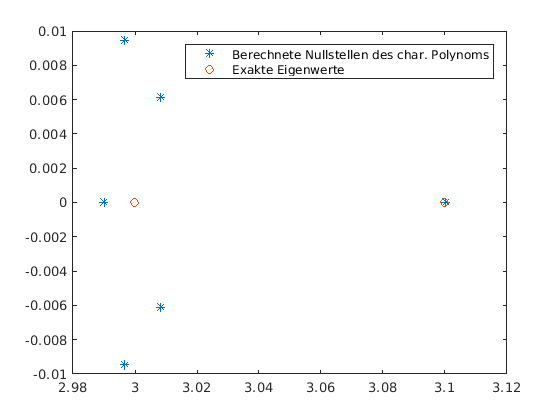

plot(real(result),imag(result),'*');
hold on;
exakt=[3.1 3];
plot(real(exakt),imag(exakt),'o');
legend('Berechnete Nullstellen des char. Polynoms','Exakte Eigenwerte');
hold off